entrada = wdesejada.signals.values;
velocidade = wreal.signals.values;

% definição de tempo
Np = length(entrada); 
Ts = 2/1000;
tempo = 0 : Ts : (Np-1)*Ts; 


x0 = [1 1]

x0 =      1     1



X = fminsearch(@(x) ErroQuadratico(x, entrada, velocidade, tempo'), x0)

X =   132.9691    5.8435



% parametros usados no modelo
Km = X(1);
pm = X(2);

Gp = tf(Km, [1 pm]) %% função transferencia do modelo


Gp =
 
     133
  ---------
  s + 5.844
 
Continuous-time transfer function.



Gp_int = Gp * tf(1, [1 0])


Gp_int =
 
       133
  -------------
  s^2 + 5.844 s
 
Continuous-time transfer function.



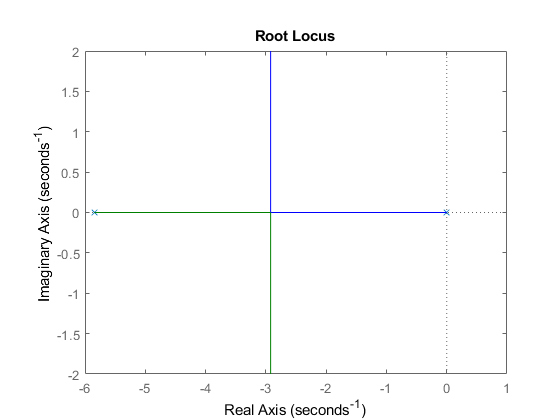

rlocus(Gp_int)

s = -2.922;
Gp_s = evalfr(Gp_int, s)

Gp_s = -15.5761

k = -1/Gp_s %%%% k que não oscila -> podre, não roda

k = 0.0642

Gmalha = k*Gp_s

Gmalha = -1

w = 24*pi;
s_w = -2.922 + w*1i;

Gp_sw = evalfr(Gp_int, s_w)

Gp_sw = -0.0234 + 0.0000i


k_w = -1/ Gp_sw

k_w = 42.8177 + 0.0003i


Gmalha_w = k_w*Gp_sw

Gmalha_w = -1.0000 + 0.0000i

function [Eq] = ErroQuadratico(X,u,y,t)
% Esta função determina o erro quadrático
% entre a saída real e a saída do modelo.
% u - entrada real
% y - saída real
% t - tempo real
% X = [Km pm];

Km= X(1);
pm = X(2);

%%% Modelo

Gp = tf(Km, [1 pm]);

%%% Saida do modelo

ym = lsim(Gp, u, t);

%%% Erro quadrático

Eq = sum((y-ym).^2); %% cálculo do erro

% plot(t,y,t,ym,"linewidth", 2)

end